% calculate Radiomics for All new Selected 
%1- Read and process the original Image and Normal Lymphnode 1

NL1_Img = dicomread("Straight_Lateral_output.dcm")

NL1_Img = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

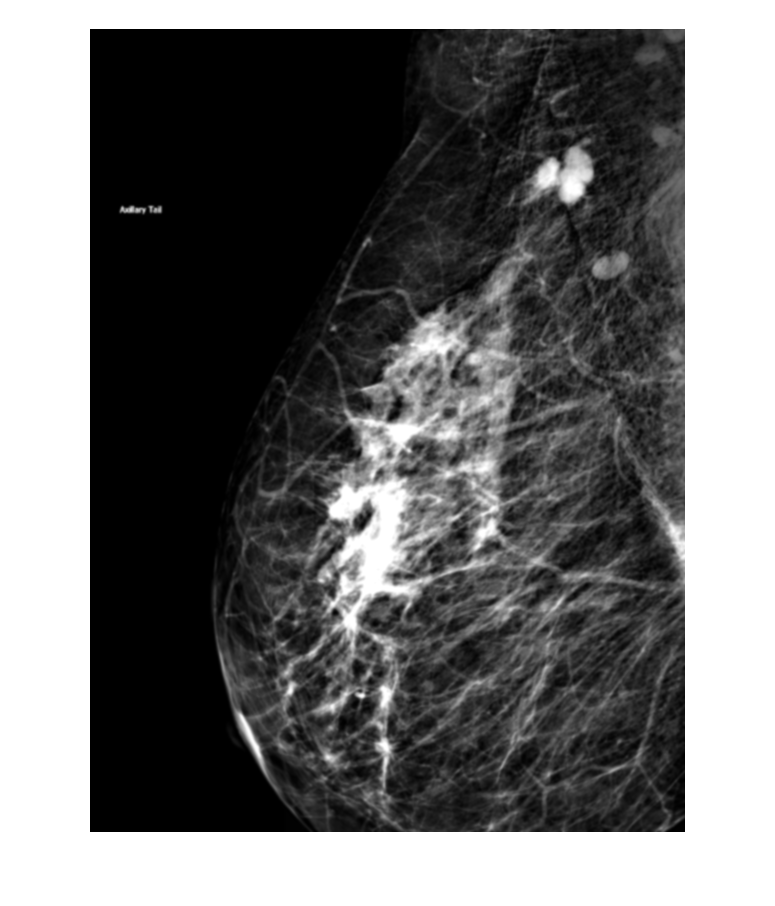

NL1_Img = im2gray(NL1_Img);
imshow(NL1_Img(:,:,1),[])

NL1_Img = cat(3, NL1_Img, zeros([size(NL1_Img) 2], class(NL1_Img)));
volGeometry = medicalref3d(size(NL1_Img));
Data = medicalVolume(NL1_Img, volGeometry);
Data.Voxels = squeeze(Data.Voxels);
%
matFilePath = 'MedicalLabelingSession_multi_Nor_Lymph1/LabelData/Straight_Lateral_output.mat';
loadedData = load(matFilePath);
fieldNames = fieldnames(loadedData);
disp(fieldNames);

    {'labels'}



Maskimg = loadedData.labels

Maskimg = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

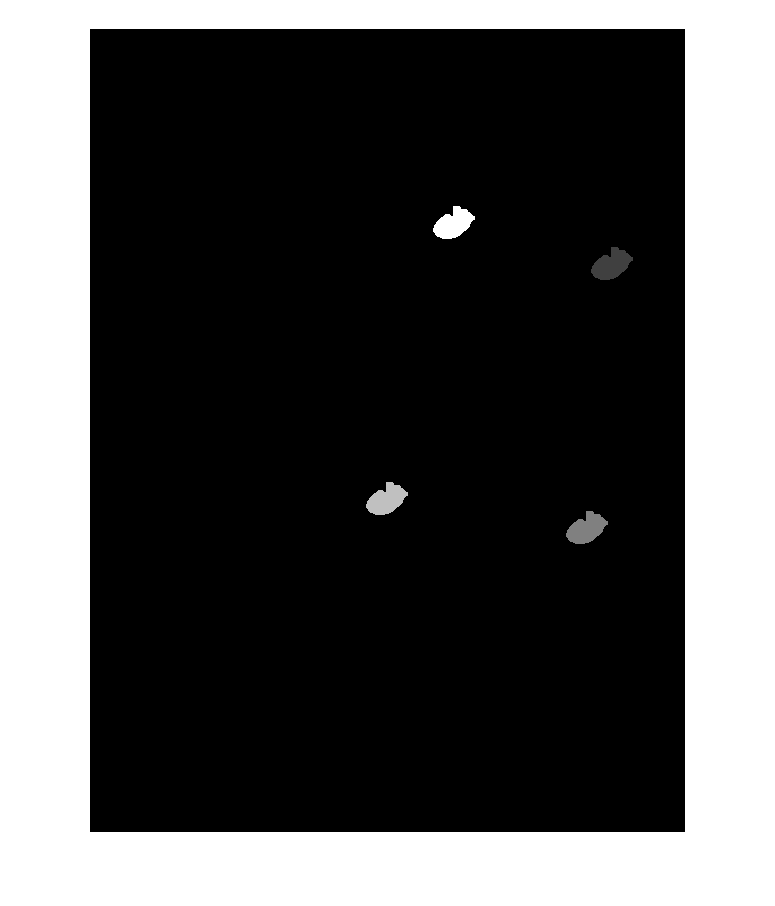

% Read and process the mask image
imshow(Maskimg(:,:,1),[])

    Maskimg = im2uint8(Maskimg);
    Maskimg = cat(3,Maskimg,zeros([size(Maskimg) 2],class(Maskimg)));
    volGeometry = medicalref3d(size(Maskimg));
    RoiData = medicalVolume(Maskimg,volGeometry);
    RoiData.Voxels = squeeze(RoiData.Voxels);



% Call the radiomics function
NL1_R = radiomics(Data, RoiData);
% around 10 seconds

% Extract intensity features
NL1_Int = intensityFeatures(NL1_R,Type="all",SubType="2D")

NL1_Int = 4×50 table
    LabelID    LocalIntensityPeak2D    GlobalIntensityPeak2D    MeanIntensity2D    IntensityVariance2D    IntensitySkewness2D    IntensityKurtosis2D    MedianIntensity2D    MinimumIntensity2D    TenthIntensityPercentile2D    NinetiethIntensityPercentile2D    MaximumIntensity2D    IntensityInterquartileRange2D    IntensityRange2D    MeanAbsoluteDeviation2D    RobustMeanAbsoluteDeviation2D    MedianAbsoluteDeviation2D    CoefficientOfVariation2D    QuartileCoefficientOfDispersion2D    IntensityEnergy2D    RootMeanSquare2D    MeanDiscretisedIntensity2D    DiscretisedIntensityVariance2D

% around 10 seconds
%% Extract texture features
NL1_tex = textureFeatures(NL1_R,Type="all",SubType="2D")

NL1_tex = 4×137 table
    LabelID    JointMaximumAveraged2D    JointAverageAveraged2D    JointVarianceAveraged2D    JointEntropyAveraged2D    DifferenceAverageAveraged2D    DifferenceVarianceAveraged2D    DifferenceEntropyAveraged2D    SumAverageAveraged2D    SumVarianceAveraged2D    SumEntropyAveraged2D    AngularSecondMomentAveraged2D    ContrastAveraged2D    DissimilarityAveraged2D    InverseDifferenceAveraged2D    NormalisedInverseDifferenceAveraged2D    InverseDifferenceMomentAveraged2D    NormalisedInverseDifferenceMomentAveraged2D    InverseVarianceAveraged2D    CorrelationAveraged2D    AutoCorrelationAveraged2D    Clust

% around 10 seconds
% Extract shape features
NL1_S = shapeFeatures(NL1_R, SubType="2D");
NL1_S = removevars(NL1_S, "LabelID");
NLradiomicsFeaturesTrain = NL1_S

NLradiomicsFeaturesTrain = 4×23 table
    VolumeMesh2D    VolumeVoxelCount2D    SurfaceAreaMesh2D    SurfaceVolumeRatio2D    Compactness1_2D    Compactness2_2D    SphericalDisproportion2D    Sphericity2D    Asphericity2D    CentreOfMassShift2D    Maximum3dDiameter2D    MajorAxisLength2D    MinorAxisLength2D    LeastAxisLength2D    Elongation2D    Flatness2D    VolumeDensityAABB_2D    AreaDensityAABB_2D    VolumeDensityAEE_2D    AreaDensityAEE_2D    VolumeDensityConvexHull2D    AreaDensityConvexHull2D    IntegratedIntensity2D
    ____________    __________________    <s

% calculate Radiomics for All new Selected 
%1- Read and process the original Image and Normal Lymphnode 2

NL1_Img = dicomread("Straight_Lateral_output.dcm")

NL1_Img = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

NL1_Img = im2gray(NL1_Img);
imshow(NL1_Img(:,:,1),[])

NL1_Img = cat(3, NL1_Img, zeros([size(NL1_Img) 2], class(NL1_Img)));
volGeometry = medicalref3d(size(NL1_Img));
Data = medicalVolume(NL1_Img, volGeometry);
Data.Voxels = squeeze(Data.Voxels);
%
matFilePath = 'MedicalLabelingSession_multi_Nor_Lymph2/LabelData/Straight_Lateral_output.mat';
loadedData = load(matFilePath);
fieldNames = fieldnames(loadedData);
disp(fieldNames);

    {'labels'}



Maskimg = loadedData.labels

Maskimg = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

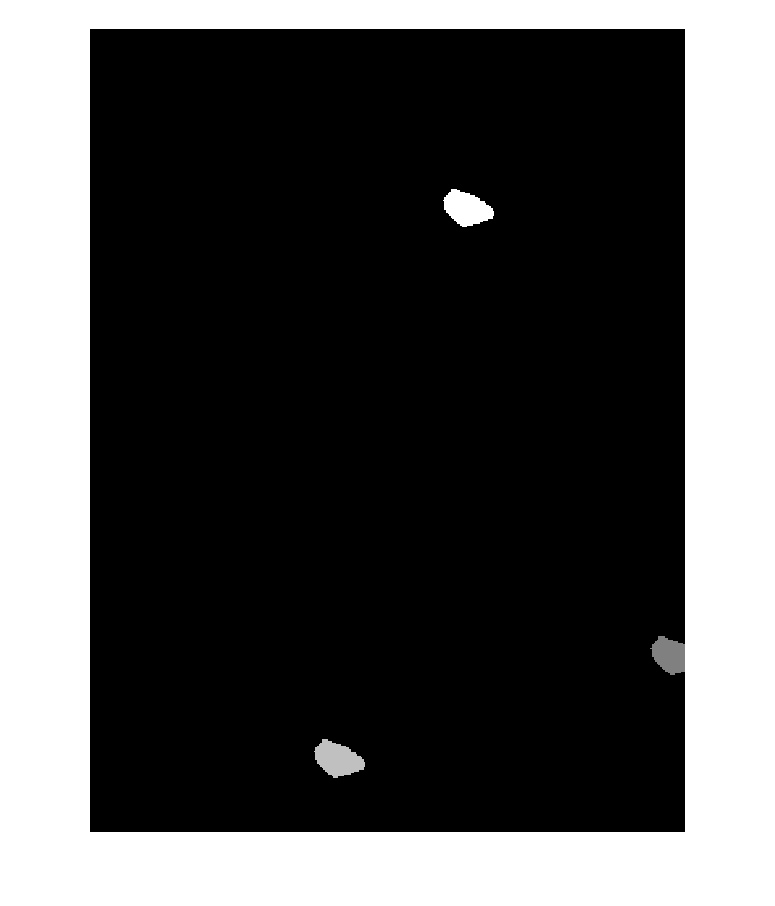

% Read and process the mask image
imshow(Maskimg(:,:,1),[])

    Maskimg = im2uint8(Maskimg);
    Maskimg = cat(3,Maskimg,zeros([size(Maskimg) 2],class(Maskimg)));
    volGeometry = medicalref3d(size(Maskimg));
    RoiData = medicalVolume(Maskimg,volGeometry);
    RoiData.Voxels = squeeze(RoiData.Voxels);



% Call the radiomics function
NL2_R = radiomics(Data, RoiData);
% around 10 seconds

% Extract intensity features
NL2_Int = intensityFeatures(NL2_R,Type="all",SubType="2D")

NL2_Int = 4×50 table
    LabelID    LocalIntensityPeak2D    GlobalIntensityPeak2D    MeanIntensity2D    IntensityVariance2D    IntensitySkewness2D    IntensityKurtosis2D    MedianIntensity2D    MinimumIntensity2D    TenthIntensityPercentile2D    NinetiethIntensityPercentile2D    MaximumIntensity2D    IntensityInterquartileRange2D    IntensityRange2D    MeanAbsoluteDeviation2D    RobustMeanAbsoluteDeviation2D    MedianAbsoluteDeviation2D    CoefficientOfVariation2D    QuartileCoefficientOfDispersion2D    IntensityEnergy2D    RootMeanSquare2D    MeanDiscretisedIntensity2D    DiscretisedIntensityVariance2D

% around 10 seconds
%% Extract texture features
NL2_tex = textureFeatures(NL2_R,Type="all",SubType="2D")

NL2_tex = 4×137 table
    LabelID    JointMaximumAveraged2D    JointAverageAveraged2D    JointVarianceAveraged2D    JointEntropyAveraged2D    DifferenceAverageAveraged2D    DifferenceVarianceAveraged2D    DifferenceEntropyAveraged2D    SumAverageAveraged2D    SumVarianceAveraged2D    SumEntropyAveraged2D    AngularSecondMomentAveraged2D    ContrastAveraged2D    DissimilarityAveraged2D    InverseDifferenceAveraged2D    NormalisedInverseDifferenceAveraged2D    InverseDifferenceMomentAveraged2D    NormalisedInverseDifferenceMomentAveraged2D    InverseVarianceAveraged2D    CorrelationAveraged2D    AutoCorrelationAveraged2D    Clust

% around 10 seconds
% Extract shape features
NL2_S = shapeFeatures(NL2_R, SubType="2D");
NL2_S = removevars(NL2_S, "LabelID");
NLradiomicsFeaturesTrain = NL2_S

NLradiomicsFeaturesTrain = 4×23 table
    VolumeMesh2D    VolumeVoxelCount2D    SurfaceAreaMesh2D    SurfaceVolumeRatio2D    Compactness1_2D    Compactness2_2D    SphericalDisproportion2D    Sphericity2D    Asphericity2D    CentreOfMassShift2D    Maximum3dDiameter2D    MajorAxisLength2D    MinorAxisLength2D    LeastAxisLength2D    Elongation2D    Flatness2D    VolumeDensityAABB_2D    AreaDensityAABB_2D    VolumeDensityAEE_2D    AreaDensityAEE_2D    VolumeDensityConvexHull2D    AreaDensityConvexHull2D    IntegratedIntensity2D
    ____________    __________________    <s

% calculate Radiomics for All new Selected 
%1- Read and process the original Image and Normal Lymphnode 3

NL1_Img = dicomread("Straight_Lateral_output.dcm")

NL1_Img = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

NL1_Img = im2gray(NL1_Img);
imshow(NL1_Img(:,:,1),[])

NL1_Img = cat(3, NL1_Img, zeros([size(NL1_Img) 2], class(NL1_Img)));
volGeometry = medicalref3d(size(NL1_Img));
Data = medicalVolume(NL1_Img, volGeometry);
Data.Voxels = squeeze(Data.Voxels);
%
matFilePath = 'MedicalLabelingSession_multi_Nor_Lymph3/LabelData/Straight_Lateral_output.mat';
loadedData = load(matFilePath);
fieldNames = fieldnames(loadedData);
disp(fieldNames);

    {'labels'}



Maskimg = loadedData.labels

Maskimg = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

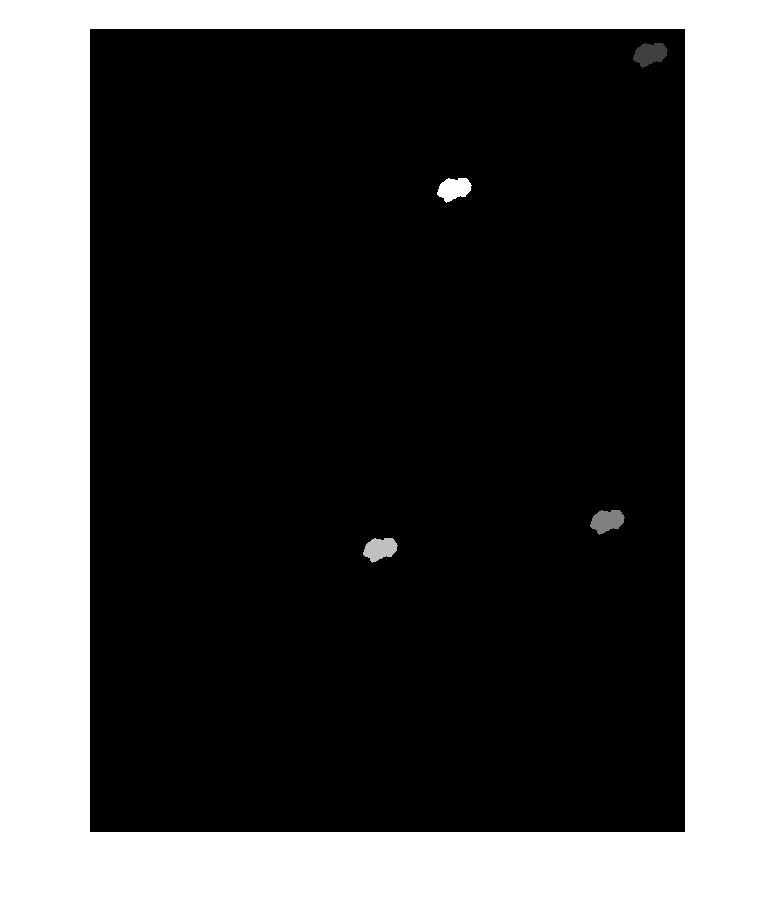

% Read and process the mask image
imshow(Maskimg(:,:,1),[])

    Maskimg = im2uint8(Maskimg);
    Maskimg = cat(3,Maskimg,zeros([size(Maskimg) 2],class(Maskimg)));
    volGeometry = medicalref3d(size(Maskimg));
    RoiData = medicalVolume(Maskimg,volGeometry);
    RoiData.Voxels = squeeze(RoiData.Voxels);



% Call the radiomics function
NL3_R = radiomics(Data, RoiData);
% around 10 seconds

% Extract intensity features
NL3_Int = intensityFeatures(NL3_R,Type="all",SubType="2D")

NL3_Int = 4×50 table
    LabelID    LocalIntensityPeak2D    GlobalIntensityPeak2D    MeanIntensity2D    IntensityVariance2D    IntensitySkewness2D    IntensityKurtosis2D    MedianIntensity2D    MinimumIntensity2D    TenthIntensityPercentile2D    NinetiethIntensityPercentile2D    MaximumIntensity2D    IntensityInterquartileRange2D    IntensityRange2D    MeanAbsoluteDeviation2D    RobustMeanAbsoluteDeviation2D    MedianAbsoluteDeviation2D    CoefficientOfVariation2D    QuartileCoefficientOfDispersion2D    IntensityEnergy2D    RootMeanSquare2D    MeanDiscretisedIntensity2D    DiscretisedIntensityVariance2D

% around 10 seconds
%% Extract texture features
NL3_tex = textureFeatures(NL3_R,Type="all",SubType="2D")

NL3_tex = 4×137 table
    LabelID    JointMaximumAveraged2D    JointAverageAveraged2D    JointVarianceAveraged2D    JointEntropyAveraged2D    DifferenceAverageAveraged2D    DifferenceVarianceAveraged2D    DifferenceEntropyAveraged2D    SumAverageAveraged2D    SumVarianceAveraged2D    SumEntropyAveraged2D    AngularSecondMomentAveraged2D    ContrastAveraged2D    DissimilarityAveraged2D    InverseDifferenceAveraged2D    NormalisedInverseDifferenceAveraged2D    InverseDifferenceMomentAveraged2D    NormalisedInverseDifferenceMomentAveraged2D    InverseVarianceAveraged2D    CorrelationAveraged2D    AutoCorrelationAveraged2D    Clust

% around 10 seconds
% Extract shape features
NL3_S = shapeFeatures(NL3_R, SubType="2D");
NL3_S = removevars(NL3_S, "LabelID");
NLradiomicsFeaturesTrain = NL3_S

NLradiomicsFeaturesTrain = 4×23 table
    VolumeMesh2D    VolumeVoxelCount2D    SurfaceAreaMesh2D    SurfaceVolumeRatio2D    Compactness1_2D    Compactness2_2D    SphericalDisproportion2D    Sphericity2D    Asphericity2D    CentreOfMassShift2D    Maximum3dDiameter2D    MajorAxisLength2D    MinorAxisLength2D    LeastAxisLength2D    Elongation2D    Flatness2D    VolumeDensityAABB_2D    AreaDensityAABB_2D    VolumeDensityAEE_2D    AreaDensityAEE_2D    VolumeDensityConvexHull2D    AreaDensityConvexHull2D    IntegratedIntensity2D
    ____________    __________________    <s

% calculate Radiomics for All new Selected 
%1- Read and process the original Image and Normal Lymphnode 4

NL1_Img = dicomread("Straight_Lateral_output.dcm")

NL1_Img = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

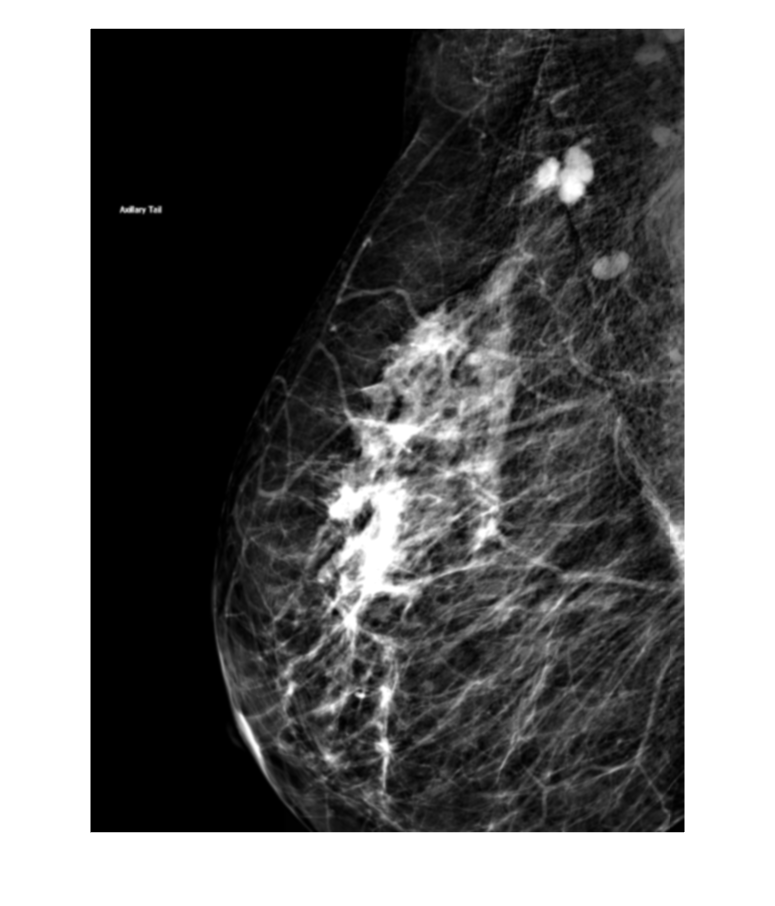

NL1_Img = im2gray(NL1_Img);
imshow(NL1_Img(:,:,1),[])

NL1_Img = cat(3, NL1_Img, zeros([size(NL1_Img) 2], class(NL1_Img)));
volGeometry = medicalref3d(size(NL1_Img));
Data = medicalVolume(NL1_Img, volGeometry);
Data.Voxels = squeeze(Data.Voxels);
%
matFilePath = 'MedicalLabelingSession_multi_Nor_Lymph4/LabelData/Straight_Lateral_output.mat';
loadedData = load(matFilePath);
fieldNames = fieldnames(loadedData);
disp(fieldNames);

    {'labels'}



Maskimg = loadedData.labels

Maskimg = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

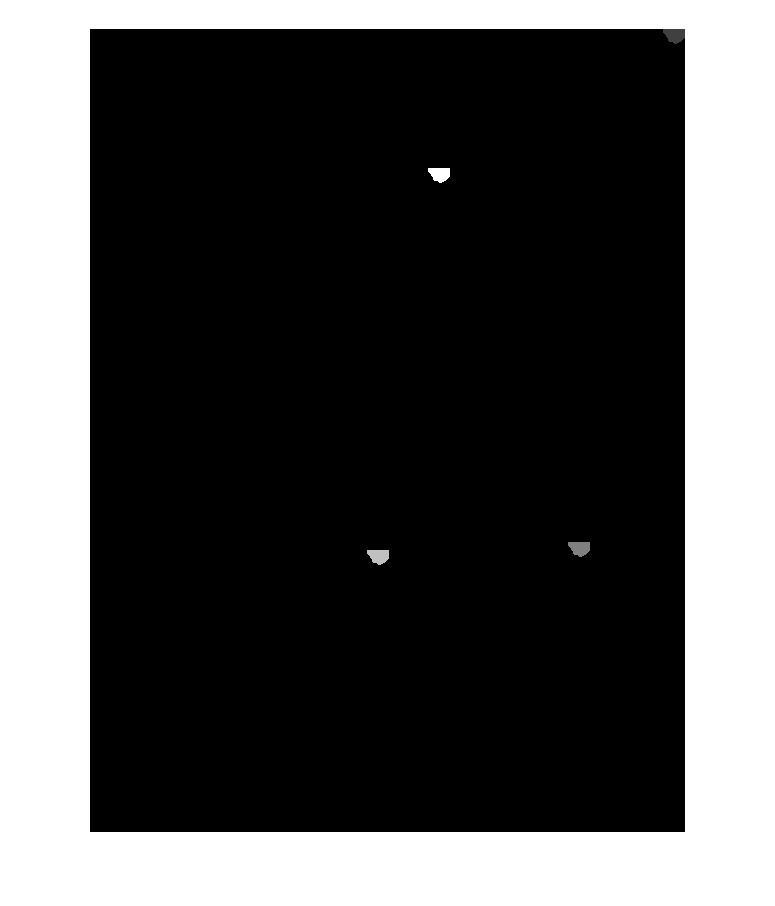

% Read and process the mask image
imshow(Maskimg(:,:,1),[])

    Maskimg = im2uint8(Maskimg);
    Maskimg = cat(3,Maskimg,zeros([size(Maskimg) 2],class(Maskimg)));
    volGeometry = medicalref3d(size(Maskimg));
    RoiData = medicalVolume(Maskimg,volGeometry);
    RoiData.Voxels = squeeze(RoiData.Voxels);



% Call the radiomics function
NL4_R = radiomics(Data, RoiData);
% around 10 seconds

% Extract intensity features
NL4_Int = intensityFeatures(NL4_R,Type="all",SubType="2D")

NL4_Int = 4×50 table
    LabelID    LocalIntensityPeak2D    GlobalIntensityPeak2D    MeanIntensity2D    IntensityVariance2D    IntensitySkewness2D    IntensityKurtosis2D    MedianIntensity2D    MinimumIntensity2D    TenthIntensityPercentile2D    NinetiethIntensityPercentile2D    MaximumIntensity2D    IntensityInterquartileRange2D    IntensityRange2D    MeanAbsoluteDeviation2D    RobustMeanAbsoluteDeviation2D    MedianAbsoluteDeviation2D    CoefficientOfVariation2D    QuartileCoefficientOfDispersion2D    IntensityEnergy2D    RootMeanSquare2D    MeanDiscretisedIntensity2D    DiscretisedIntensityVariance2D

% around 10 seconds
%% Extract texture features
NL4_tex = textureFeatures(NL4_R,Type="all",SubType="2D")

NL4_tex = 4×137 table
    LabelID    JointMaximumAveraged2D    JointAverageAveraged2D    JointVarianceAveraged2D    JointEntropyAveraged2D    DifferenceAverageAveraged2D    DifferenceVarianceAveraged2D    DifferenceEntropyAveraged2D    SumAverageAveraged2D    SumVarianceAveraged2D    SumEntropyAveraged2D    AngularSecondMomentAveraged2D    ContrastAveraged2D    DissimilarityAveraged2D    InverseDifferenceAveraged2D    NormalisedInverseDifferenceAveraged2D    InverseDifferenceMomentAveraged2D    NormalisedInverseDifferenceMomentAveraged2D    InverseVarianceAveraged2D    CorrelationAveraged2D    AutoCorrelationAveraged2D    Clust

% around 10 seconds
% Extract shape features
NL4_S = shapeFeatures(NL4_R, SubType="2D");
NL4_S = removevars(NL4_S, "LabelID");
NLradiomicsFeaturesTrain = NL4_S

NLradiomicsFeaturesTrain = 4×23 table
    VolumeMesh2D    VolumeVoxelCount2D    SurfaceAreaMesh2D    SurfaceVolumeRatio2D    Compactness1_2D    Compactness2_2D    SphericalDisproportion2D    Sphericity2D    Asphericity2D    CentreOfMassShift2D    Maximum3dDiameter2D    MajorAxisLength2D    MinorAxisLength2D    LeastAxisLength2D    Elongation2D    Flatness2D    VolumeDensityAABB_2D    AreaDensityAABB_2D    VolumeDensityAEE_2D    AreaDensityAEE_2D    VolumeDensityConvexHull2D    AreaDensityConvexHull2D    IntegratedIntensity2D
    ____________    __________________    <s

% calculate Radiomics for All new Selected 
%1- Read and process the original Image and Intense Lymphnode 1

NL1_Img = dicomread("Straight_Lateral_output.dcm")

NL1_Img = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

NL1_Img = im2gray(NL1_Img);
imshow(NL1_Img(:,:,1),[])

NL1_Img = cat(3, NL1_Img, zeros([size(NL1_Img) 2], class(NL1_Img)));
volGeometry = medicalref3d(size(NL1_Img));
Data = medicalVolume(NL1_Img, volGeometry);
Data.Voxels = squeeze(Data.Voxels);
%
matFilePath = 'MedicalLabelingSession_Multi_intens_lymph1/LabelData/Straight_Lateral_output.mat';
loadedData = load(matFilePath);
fieldNames = fieldnames(loadedData);
disp(fieldNames);

    {'labels'}



Maskimg = loadedData.labels

Maskimg = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

% Read and process the mask image
imshow(Maskimg(:,:,1),[])
    Maskimg = im2uint8(Maskimg);
    Maskimg = cat(3,Maskimg,zeros([size(Maskimg) 2],class(Maskimg)));
    volGeometry = medicalref3d(size(Maskimg));
    RoiData = medicalVolume(Maskimg,volGeometry);
    RoiData.Voxels = squeeze(RoiData.Voxels);



% Call the radiomics function
IL1_R = radiomics(Data, RoiData);
% around 10 seconds

% Extract intensity features
IL1_Int = intensityFeatures(IL1_R,Type="all",SubType="2D")

IL1_Int = 4×50 table
    LabelID    LocalIntensityPeak2D    GlobalIntensityPeak2D    MeanIntensity2D    IntensityVariance2D    IntensitySkewness2D    IntensityKurtosis2D    MedianIntensity2D    MinimumIntensity2D    TenthIntensityPercentile2D    NinetiethIntensityPercentile2D    MaximumIntensity2D    IntensityInterquartileRange2D    IntensityRange2D    MeanAbsoluteDeviation2D    RobustMeanAbsoluteDeviation2D    MedianAbsoluteDeviation2D    CoefficientOfVariation2D    QuartileCoefficientOfDispersion2D    IntensityEnergy2D    RootMeanSquare2D    MeanDiscretisedIntensity2D    DiscretisedIntensityVariance2D

% around 10 seconds
%% Extract texture features
IL1_tex = textureFeatures(IL1_R,Type="all",SubType="2D")

IL1_tex = 4×137 table
    LabelID    JointMaximumAveraged2D    JointAverageAveraged2D    JointVarianceAveraged2D    JointEntropyAveraged2D    DifferenceAverageAveraged2D    DifferenceVarianceAveraged2D    DifferenceEntropyAveraged2D    SumAverageAveraged2D    SumVarianceAveraged2D    SumEntropyAveraged2D    AngularSecondMomentAveraged2D    ContrastAveraged2D    DissimilarityAveraged2D    InverseDifferenceAveraged2D    NormalisedInverseDifferenceAveraged2D    InverseDifferenceMomentAveraged2D    NormalisedInverseDifferenceMomentAveraged2D    InverseVarianceAveraged2D    CorrelationAveraged2D    AutoCorrelationAveraged2D    Clust

% around 10 seconds
% Extract shape features
IL1_S = shapeFeatures(IL1_R, SubType="2D");
IL1_S = removevars(IL1_S, "LabelID");
NLradiomicsFeaturesTrain = IL1_S

NLradiomicsFeaturesTrain = 4×23 table
    VolumeMesh2D    VolumeVoxelCount2D    SurfaceAreaMesh2D    SurfaceVolumeRatio2D    Compactness1_2D    Compactness2_2D    SphericalDisproportion2D    Sphericity2D    Asphericity2D    CentreOfMassShift2D    Maximum3dDiameter2D    MajorAxisLength2D    MinorAxisLength2D    LeastAxisLength2D    Elongation2D    Flatness2D    VolumeDensityAABB_2D    AreaDensityAABB_2D    VolumeDensityAEE_2D    AreaDensityAEE_2D    VolumeDensityConvexHull2D    AreaDensityConvexHull2D    IntegratedIntensity2D
    ____________    __________________    <s

% calculate Radiomics for All new Selected 
%1- Read and process the original Image and Intense Lymphnode 2

NL1_Img = dicomread("Straight_Lateral_output.dcm")

NL1_Img = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

NL1_Img = im2gray(NL1_Img);
imshow(NL1_Img(:,:,1),[])

NL1_Img = cat(3, NL1_Img, zeros([size(NL1_Img) 2], class(NL1_Img)));
volGeometry = medicalref3d(size(NL1_Img));
Data = medicalVolume(NL1_Img, volGeometry);
Data.Voxels = squeeze(Data.Voxels);
%
matFilePath = 'MedicalLabelingSession_Multi_intens_lymph2/LabelData/Straight_Lateral_output.mat';
loadedData = load(matFilePath);
fieldNames = fieldnames(loadedData);
disp(fieldNames);

    {'labels'}



Maskimg = loadedData.labels

Maskimg = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

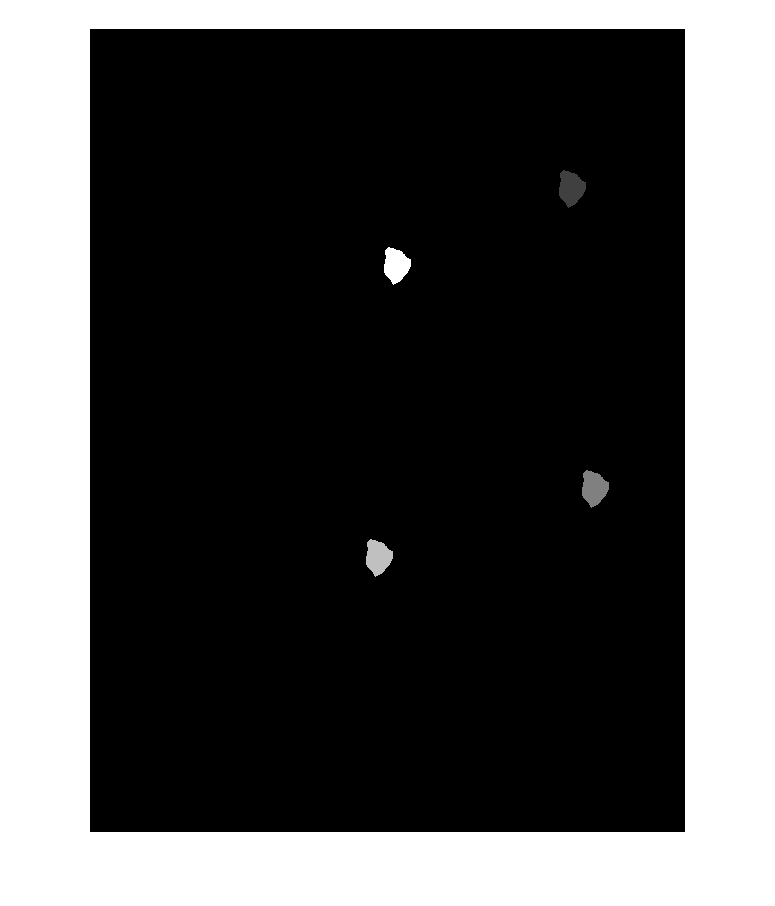

% Read and process the mask image
imshow(Maskimg(:,:,1),[])

    Maskimg = im2uint8(Maskimg);
    Maskimg = cat(3,Maskimg,zeros([size(Maskimg) 2],class(Maskimg)));
    volGeometry = medicalref3d(size(Maskimg));
    RoiData = medicalVolume(Maskimg,volGeometry);
    RoiData.Voxels = squeeze(RoiData.Voxels);



% Call the radiomics function
IL2_R = radiomics(Data, RoiData);
% around 10 seconds

% Extract intensity features
IL2_Int = intensityFeatures(IL2_R,Type="all",SubType="2D")

IL2_Int = 4×50 table
    LabelID    LocalIntensityPeak2D    GlobalIntensityPeak2D    MeanIntensity2D    IntensityVariance2D    IntensitySkewness2D    IntensityKurtosis2D    MedianIntensity2D    MinimumIntensity2D    TenthIntensityPercentile2D    NinetiethIntensityPercentile2D    MaximumIntensity2D    IntensityInterquartileRange2D    IntensityRange2D    MeanAbsoluteDeviation2D    RobustMeanAbsoluteDeviation2D    MedianAbsoluteDeviation2D    CoefficientOfVariation2D    QuartileCoefficientOfDispersion2D    IntensityEnergy2D    RootMeanSquare2D    MeanDiscretisedIntensity2D    DiscretisedIntensityVariance2D

% around 10 seconds
%% Extract texture features
IL2_tex = textureFeatures(IL2_R,Type="all",SubType="2D")

IL2_tex = 4×137 table
    LabelID    JointMaximumAveraged2D    JointAverageAveraged2D    JointVarianceAveraged2D    JointEntropyAveraged2D    DifferenceAverageAveraged2D    DifferenceVarianceAveraged2D    DifferenceEntropyAveraged2D    SumAverageAveraged2D    SumVarianceAveraged2D    SumEntropyAveraged2D    AngularSecondMomentAveraged2D    ContrastAveraged2D    DissimilarityAveraged2D    InverseDifferenceAveraged2D    NormalisedInverseDifferenceAveraged2D    InverseDifferenceMomentAveraged2D    NormalisedInverseDifferenceMomentAveraged2D    InverseVarianceAveraged2D    CorrelationAveraged2D    AutoCorrelationAveraged2D    Clust

% around 10 seconds
% Extract shape features
IL2_S = shapeFeatures(IL2_R, SubType="2D");
IL2_S = removevars(IL2_S, "LabelID");
NLradiomicsFeaturesTrain = IL2_S

NLradiomicsFeaturesTrain = 4×23 table
    VolumeMesh2D    VolumeVoxelCount2D    SurfaceAreaMesh2D    SurfaceVolumeRatio2D    Compactness1_2D    Compactness2_2D    SphericalDisproportion2D    Sphericity2D    Asphericity2D    CentreOfMassShift2D    Maximum3dDiameter2D    MajorAxisLength2D    MinorAxisLength2D    LeastAxisLength2D    Elongation2D    Flatness2D    VolumeDensityAABB_2D    AreaDensityAABB_2D    VolumeDensityAEE_2D    AreaDensityAEE_2D    VolumeDensityConvexHull2D    AreaDensityConvexHull2D    IntegratedIntensity2D
    ____________    __________________    <s

% calculate Radiomics for All new Selected 
%1- Read and process the original Image and Intense Lymphnode 1

NL1_Img = dicomread("Straight_Lateral_output.dcm")

NL1_Img = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

NL1_Img = im2gray(NL1_Img);
imshow(NL1_Img(:,:,1),[])
NL1_Img = cat(3, NL1_Img, zeros([size(NL1_Img) 2], class(NL1_Img)));
volGeometry = medicalref3d(size(NL1_Img));
Data = medicalVolume(NL1_Img, volGeometry);
Data.Voxels = squeeze(Data.Voxels);
%
matFilePath = 'MedicalLabelingSession_Multi_intens_lymph3/LabelData/Straight_Lateral_output.mat';
loadedData = load(matFilePath);
fieldNames = fieldnames(loadedData);
disp(fieldNames);

    {'labels'}



Maskimg = loadedData.labels

Maskimg = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

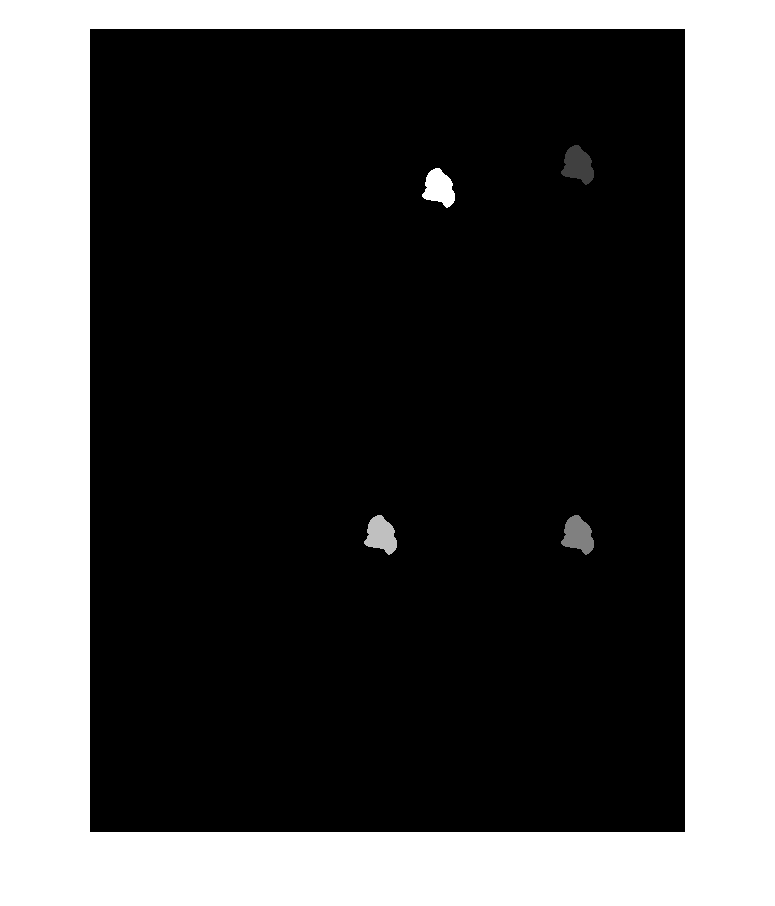

% Read and process the mask image
imshow(Maskimg(:,:,1),[])

    Maskimg = im2uint8(Maskimg);
    Maskimg = cat(3,Maskimg,zeros([size(Maskimg) 2],class(Maskimg)));
    volGeometry = medicalref3d(size(Maskimg));
    RoiData = medicalVolume(Maskimg,volGeometry);
    RoiData.Voxels = squeeze(RoiData.Voxels);

% Call the radiomics function
IL3_R = radiomics(Data, RoiData);
% around 10 seconds

% Extract intensity features
IL3_Int = intensityFeatures(IL3_R,Type="all",SubType="2D")

IL3_Int = 4×50 table
    LabelID    LocalIntensityPeak2D    GlobalIntensityPeak2D    MeanIntensity2D    IntensityVariance2D    IntensitySkewness2D    IntensityKurtosis2D    MedianIntensity2D    MinimumIntensity2D    TenthIntensityPercentile2D    NinetiethIntensityPercentile2D    MaximumIntensity2D    IntensityInterquartileRange2D    IntensityRange2D    MeanAbsoluteDeviation2D    RobustMeanAbsoluteDeviation2D    MedianAbsoluteDeviation2D    CoefficientOfVariation2D    QuartileCoefficientOfDispersion2D    IntensityEnergy2D    RootMeanSquare2D    MeanDiscretisedIntensity2D    DiscretisedIntensityVariance2D

% around 10 seconds
%% Extract texture features
IL3_tex = textureFeatures(IL3_R,Type="all",SubType="2D")

IL3_tex = 4×137 table
    LabelID    JointMaximumAveraged2D    JointAverageAveraged2D    JointVarianceAveraged2D    JointEntropyAveraged2D    DifferenceAverageAveraged2D    DifferenceVarianceAveraged2D    DifferenceEntropyAveraged2D    SumAverageAveraged2D    SumVarianceAveraged2D    SumEntropyAveraged2D    AngularSecondMomentAveraged2D    ContrastAveraged2D    DissimilarityAveraged2D    InverseDifferenceAveraged2D    NormalisedInverseDifferenceAveraged2D    InverseDifferenceMomentAveraged2D    NormalisedInverseDifferenceMomentAveraged2D    InverseVarianceAveraged2D    CorrelationAveraged2D    AutoCorrelationAveraged2D    Clust

% around 10 seconds
% Extract shape features
IL3_S = shapeFeatures(IL3_R, SubType="2D")

IL3_S = 4×24 table
    LabelID    VolumeMesh2D    VolumeVoxelCount2D    SurfaceAreaMesh2D    SurfaceVolumeRatio2D    Compactness1_2D    Compactness2_2D    SphericalDisproportion2D    Sphericity2D    Asphericity2D    CentreOfMassShift2D    Maximum3dDiameter2D    MajorAxisLength2D    MinorAxisLength2D    LeastAxisLength2D    Elongation2D    Flatness2D    VolumeDensityAABB_2D    AreaDensityAABB_2D    VolumeDensityAEE_2D    AreaDensityAEE_2D    VolumeDensityConvexHull2D    AreaDensityConvexHull2D    IntegratedIntensity2D
    _______    ____________    

IL3_S = removevars(IL3_S, "LabelID")

IL3_S = 4×23 table
    VolumeMesh2D    VolumeVoxelCount2D    SurfaceAreaMesh2D    SurfaceVolumeRatio2D    Compactness1_2D    Compactness2_2D    SphericalDisproportion2D    Sphericity2D    Asphericity2D    CentreOfMassShift2D    Maximum3dDiameter2D    MajorAxisLength2D    MinorAxisLength2D    LeastAxisLength2D    Elongation2D    Flatness2D    VolumeDensityAABB_2D    AreaDensityAABB_2D    VolumeDensityAEE_2D    AreaDensityAEE_2D    VolumeDensityConvexHull2D    AreaDensityConvexHull2D    IntegratedIntensity2D
    ____________    __________________    _____________

%extract Features from Radiomics Output for three Normal lymph
disp(IL3_tex.Properties.VariableNames);

    {'LabelID'}    {'JointMaximumAveraged2D'}    {'JointAverageAveraged2D'}    {'JointVarianceAveraged2D'}    {'JointEntropyAveraged2D'}    {'DifferenceAverageAveraged2D'}    {'DifferenceVarianceAveraged2D'}    {'DifferenceEntropyAveraged2D'}    {'SumAverageAveraged2D'}    {'SumVarianceAveraged2D'}    {'SumEntropyAveraged2D'}    {'AngularSecondMomentAveraged2D'}    {'ContrastAveraged2D'}    {'DissimilarityAveraged2D'}    {'InverseDifferenceAveraged2D'}    {'NormalisedInverseDifferenceAveraged2D'}    {'InverseDifferenceMomentAveraged2D'}    {'NormalisedInverseDifferenceMomentAveraged2D'}    {'InverseVarianceAveraged2D'}    {'CorrelationAveraged2D'}    {'AutoCorrelationAveraged2D'}    {'ClusterTendencyAveraged2D'}    {'ClusterShadeAveraged2D'}    {'ClusterProminenceAveraged2D'}    {'InformationCorrelation1Averaged2D'}    {'InformationCorrelation2Averaged2D'}    {'JointMaximumSliceMerged2D'}    {'JointAverageSliceMerged2D'}    {'JointVarianceSliceMerged2D'}    {'JointEntropySliceMerged2D'

%%%%%%%%%Normal lymph1
RadiomicsOutputN1(:,1)=NL1_tex(:,'AngularSecondMomentAveraged2D');
RadiomicsOutputN1(:,2)=NL1_Int(:,'MedianIntensity2D');
RadiomicsOutputN1(:,3)=NL1_tex(:,'RunEntropyAveraged2D');
RadiomicsOutputN1(:,4)=NL1_Int(:,'RootMeanSquare2D');
RadiomicsOutputN1(:,5)=NL1_tex(:,'HighGrayLevelRunEmphasisAveraged2D');
RadiomicsOutputN1(:,6)=NL1_S(:,'Maximum3dDiameter2D');
RadiomicsOutputN1(:,7)=NL1_tex(:,'InverseDifferenceMomentAveraged2D');
RadiomicsOutputN1(:,8)=NL1_tex(:,'LargeZoneLowGrayLevelEmphasis2D');
%%%%%%%%%Normal lymph2
RadiomicsOutputN2(:,1)=NL2_tex(:,'AngularSecondMomentAveraged2D');
RadiomicsOutputN2(:,2)=NL2_Int(:,'MedianIntensity2D');
RadiomicsOutputN2(:,3)=NL2_tex(:,'RunEntropyAveraged2D');
RadiomicsOutputN2(:,4)=NL2_Int(:,'RootMeanSquare2D');
RadiomicsOutputN2(:,5)=NL2_tex(:,'HighGrayLevelRunEmphasisAveraged2D');
RadiomicsOutputN2(:,6)=NL2_S(:,'Maximum3dDiameter2D');
RadiomicsOutputN2(:,7)=NL2_tex(:,'InverseDifferenceMomentAveraged2D');
RadiomicsOutputN2(:,8)=NL2_tex(:,'LargeZoneLowGrayLevelEmphasis2D');
%%%%%%%%%Normal Lymph3
RadiomicsOutputN3(:,1)=NL3_tex(:,'AngularSecondMomentAveraged2D');
RadiomicsOutputN3(:,2)=NL3_Int(:,'MedianIntensity2D');
RadiomicsOutputN3(:,3)=NL3_tex(:,'RunEntropyAveraged2D');
RadiomicsOutputN3(:,4)=NL3_Int(:,'RootMeanSquare2D');
RadiomicsOutputN3(:,5)=NL3_tex(:,'HighGrayLevelRunEmphasisAveraged2D');
RadiomicsOutputN3(:,6)=NL3_S(:,'Maximum3dDiameter2D');
RadiomicsOutputN3(:,7)=NL3_tex(:,'InverseDifferenceMomentAveraged2D');
RadiomicsOutputN3(:,8)=NL3_tex(:,'LargeZoneLowGrayLevelEmphasis2D');
%%%%%%%%%Normal Lymph4
RadiomicsOutputN4(:,1)=NL4_tex(:,'AngularSecondMomentAveraged2D');
RadiomicsOutputN4(:,2)=NL4_Int(:,'MedianIntensity2D');
RadiomicsOutputN4(:,3)=NL4_tex(:,'RunEntropyAveraged2D');
RadiomicsOutputN4(:,4)=NL4_Int(:,'RootMeanSquare2D');
RadiomicsOutputN4(:,5)=NL4_tex(:,'HighGrayLevelRunEmphasisAveraged2D');
RadiomicsOutputN4(:,6)=NL4_S(:,'Maximum3dDiameter2D');
RadiomicsOutputN4(:,7)=NL4_tex(:,'InverseDifferenceMomentAveraged2D');
RadiomicsOutputN4(:,8)=NL4_tex(:,'LargeZoneLowGrayLevelEmphasis2D');


RadiomicsOutputN1 = 4×8 table
    AngularSecondMomentAveraged2D    Var2     Var3      Var4      Var5      Var6      Var7       Var8 
    _____________________________    ____    ______    ______    ______    ______    _______    ______

              0.037685               111     4.8183    111.81    85.907    44.598    0.66858    2.2574
              0.031936                46     5.0379    57.915    46.826    44.598    0.67345    35.602
               0.45147               254     4.9071    237.46       130    44.598    0.86469    28.574
              0.035086                31     4.7261    32.005    58.846    44.598    0.65167    5.7741


RadiomicsOutputN2 = 4×8 table
    AngularSecondMomentAveraged2D    Var2     Var3      Var4      Var5      Var6      Var7       Var8 
    _____________________________    ____    ______    ______    ______    ______    _______    ______

               0.13866               87.5    4.0951    86.422    11.163    33.242    0.81081    126.44
               0.18063               65.5    4.4512    69.734    7.6109    33.242    0.85344    605.27
               0.92759                255    3.9971    254.08    20.828    33.242    0.98176    1263.4
               0.18722                 27    4.3318    28.804    5.8488    33.242     0.8518    1340.4


RadiomicsOutputN3 = 4×8 table
    AngularSecondMomentAveraged2D    Var2     Var3      Var4      Var5      Var6      Var7       Var8 
    _____________________________    ____    ______    ______    ______    ______    _______    ______

               0.12486                63     4.4004    63.477    15.763    36.139    0.82468     161.8
               0.11322                44     4.5301    51.296    10.511    36.139    0.82804     735.9
                 0.791               255     4.3423    250.73    24.422    36.139    0.95549    563.45
               0.15062                25     4.5158    28.135    8.8602    36.139    0.83871    802.95


RadiomicsOutputN4 = 4×8 table
    AngularSecondMomentAveraged2D    Var2     Var3      Var4      Var5      Var6      Var7       Var8 
    _____________________________    ____    ______    ______    ______    ______    _______    ______

               0.23866                82     3.9262    80.511    13.645    23.409    0.83717    83.009
               0.10495                25     3.9299    26.653    8.4532    23.409    0.76464    97.666
                     1               255     3.3957       255     16384    23.409          1    3.8453
               0.11471                18     4.0818    18.226    9.5335    23.409    0.78862     158.8


%extract Features from Radiomics Output for three intense lymph
%%%%%%%%%intens lymph1
RadiomicsOutputI1(:,1)=IL1_tex(:,'AngularSecondMomentAveraged2D');
RadiomicsOutputI1(:,2)=IL1_Int(:,'MedianIntensity2D');
RadiomicsOutputI1(:,3)=IL1_tex(:,'RunEntropyAveraged2D');
RadiomicsOutputI1(:,4)=IL1_Int(:,'RootMeanSquare2D');
RadiomicsOutputI1(:,5)=IL1_tex(:,'HighGrayLevelRunEmphasisAveraged2D');
RadiomicsOutputI1(:,6)=IL1_S(:,'Maximum3dDiameter2D');
RadiomicsOutputI1(:,7)=IL1_tex(:,'InverseDifferenceMomentAveraged2D');
RadiomicsOutputI1(:,8)=IL1_tex(:,'LargeZoneLowGrayLevelEmphasis2D');
%%%%%%%%%intens lymph2
RadiomicsOutputI2(:,1)=IL2_tex(:,'AngularSecondMomentAveraged2D');
RadiomicsOutputI2(:,2)=IL2_Int(:,'MedianIntensity2D');
RadiomicsOutputI2(:,3)=IL2_tex(:,'RunEntropyAveraged2D');
RadiomicsOutputI2(:,4)=IL2_Int(:,'RootMeanSquare2D');
RadiomicsOutputI2(:,5)=IL2_tex(:,'HighGrayLevelRunEmphasisAveraged2D');
RadiomicsOutputI2(:,6)=IL2_S(:,'Maximum3dDiameter2D');
RadiomicsOutputI2(:,7)=IL2_tex(:,'InverseDifferenceMomentAveraged2D');
RadiomicsOutputI2(:,8)=IL2_tex(:,'LargeZoneLowGrayLevelEmphasis2D');
%%%%%%%%%intensLymph3
RadiomicsOutputI3(:,1)=IL3_tex(:,'AngularSecondMomentAveraged2D');
RadiomicsOutputI3(:,2)=IL3_Int(:,'MedianIntensity2D');
RadiomicsOutputI3(:,3)=IL3_tex(:,'RunEntropyAveraged2D');
RadiomicsOutputI3(:,4)=IL3_Int(:,'RootMeanSquare2D');
RadiomicsOutputI3(:,5)=IL3_tex(:,'HighGrayLevelRunEmphasisAveraged2D');
RadiomicsOutputI3(:,6)=IL3_S(:,'Maximum3dDiameter2D');
RadiomicsOutputI3(:,7)=IL3_tex(:,'InverseDifferenceMomentAveraged2D');
RadiomicsOutputI3(:,8)=IL3_tex(:,'LargeZoneLowGrayLevelEmphasis2D');

%  print normal lymph radiomics
RadiomicsOutputN1

RadiomicsOutputN1 = 4×8 table
    AngularSecondMomentAveraged2D    Var2     Var3      Var4      Var5      Var6      Var7       Var8 
    _____________________________    ____    ______    ______    ______    ______    _______    ______

              0.037685               111     4.8183    111.81    85.907    44.598    0.66858    2.2574
              0.031936                46     5.0379    57.915    46.826    44.598    0.67345    35.602
               0.45147               254     4.9071    237.46       130    44.598    0.86469    28.574
              0.035086                31     4.7261    32.005    58.846    44.598    0.65167    5.7741


RadiomicsOutputN2

RadiomicsOutputN2 = 4×8 table
    AngularSecondMomentAveraged2D    Var2     Var3      Var4      Var5      Var6      Var7       Var8 
    _____________________________    ____    ______    ______    ______    ______    _______    ______

               0.13866               87.5    4.0951    86.422    11.163    33.242    0.81081    126.44
               0.18063               65.5    4.4512    69.734    7.6109    33.242    0.85344    605.27
               0.92759                255    3.9971    254.08    20.828    33.242    0.98176    1263.4
               0.18722                 27    4.3318    28.804    5.8488    33.242     0.8518    1340.4


RadiomicsOutputN3

RadiomicsOutputN3 = 4×8 table
    AngularSecondMomentAveraged2D    Var2     Var3      Var4      Var5      Var6      Var7       Var8 
    _____________________________    ____    ______    ______    ______    ______    _______    ______

               0.12486                63     4.4004    63.477    15.763    36.139    0.82468     161.8
               0.11322                44     4.5301    51.296    10.511    36.139    0.82804     735.9
                 0.791               255     4.3423    250.73    24.422    36.139    0.95549    563.45
               0.15062                25     4.5158    28.135    8.8602    36.139    0.83871    802.95


RadiomicsOutputN4

RadiomicsOutputN4 = 4×8 table
    AngularSecondMomentAveraged2D    Var2     Var3      Var4      Var5      Var6      Var7       Var8 
    _____________________________    ____    ______    ______    ______    ______    _______    ______

               0.23866                82     3.9262    80.511    13.645    23.409    0.83717    83.009
               0.10495                25     3.9299    26.653    8.4532    23.409    0.76464    97.666
                     1               255     3.3957       255     16384    23.409          1    3.8453
               0.11471                18     4.0818    18.226    9.5335    23.409    0.78862     158.8


%  print intense lymph radiomics
RadiomicsOutputI1

RadiomicsOutputI1 = 4×8 table
    AngularSecondMomentAveraged2D    Var2     Var3      Var4      Var5      Var6      Var7       Var8  
    _____________________________    ____    ______    ______    ______    ______    _______    _______

              0.018487               191     5.1872    189.85    224.21    40.249    0.55194    0.29137
              0.030458                26     4.9915    39.624     68.63    40.249    0.60512     8.3558
               0.63151               255      5.033     250.7    285.86    40.249    0.85181     7.8393
              0.011104                40     4.9021    42.406    114.76    40.249    0.45184     0.3497


RadiomicsOutputI2

RadiomicsOutputI2 = 4×8 table
    AngularSecondMomentAveraged2D    Var2     Var3      Var4      Var5      Var6      Var7       Var8 
    _____________________________    ____    ______    ______    ______    ______    _______    ______

              0.076098               222     5.0014    214.21    194.07    38.328    0.66585    1.2539
              0.017428                51     4.9416     56.92    81.452    38.328    0.55844     2.348
               0.86745               255     4.6237    254.62    289.01    38.328    0.94753    32.558
              0.028474                26     5.0418    31.288    82.684    38.328    0.60308    2.4551


RadiomicsOutputI3

RadiomicsOutputI3 = 4×8 table
    AngularSecondMomentAveraged2D    Var2     Var3      Var4      Var5      Var6      Var7       Var8 
    _____________________________    ____    ______    ______    ______    ______    _______    ______

              0.031174               179     5.1741    180.51    106.69    41.761    0.66714    1.7808
              0.027561                44     5.2507    60.729     67.13    41.761     0.6447    24.516
               0.39312               255     4.7396    245.47    202.24    41.761    0.80549    10.152
               0.04093                22     4.7676    25.391    36.216    41.761     0.6407    19.081


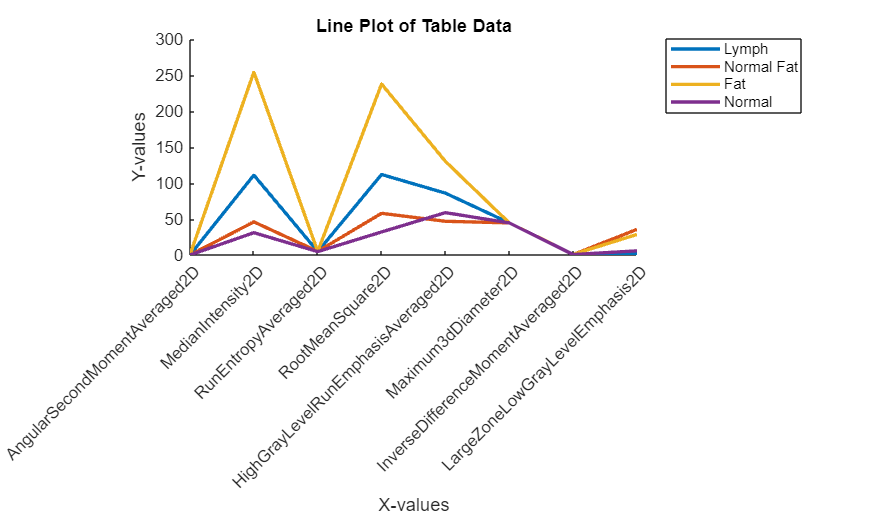


% plot Matlab Lymph node and other parameter based on Paper important
% radiomics value

columnNames = {'AngularSecondMomentAveraged2D', 'MedianIntensity2D', 'RunEntropyAveraged2D', 'RootMeanSquare2D', 'HighGrayLevelRunEmphasisAveraged2D', 'Maximum3dDiameter2D', 'InverseDifferenceMomentAveraged2D', 'LargeZoneLowGrayLevelEmphasis2D'};
rowNames = {'Lymph', 'Normal Fat', 'Fat', 'Normal'};
dataN1=table2array(RadiomicsOutputN1);
dataTableN1 = array2table(dataN1, 'VariableNames', columnNames, 'RowNames', rowNames);

% Extract data
x = dataTableN1.Properties.VariableNames; % Column names as x-values
y = table2array(dataTableN1); % Data as y-values

% Create a new figure
figure;

% Plot each row with a different color
hold on;
colors = lines(size(y, 1)); % Get a colormap with enough colors

for i = 1:size(y, 1)
    plot(1:length(x), y(i, :), 'DisplayName', dataTableN1.Properties.RowNames{i}, 'Color', colors(i, :), 'LineWidth', 2);
  
end

% Set plot properties
xticks(1:length(x));
xticklabels(x);
xtickangle(45);
xlabel('X-values');
ylabel('Y-values');
legend('show', 'Location', 'northeastoutside');
set(gcf, 'Position', get(gcf, 'Position') + [0 0 150 0]); % Increase figure width by 150 pixels
title('Line Plot of Table Data');

hold off;